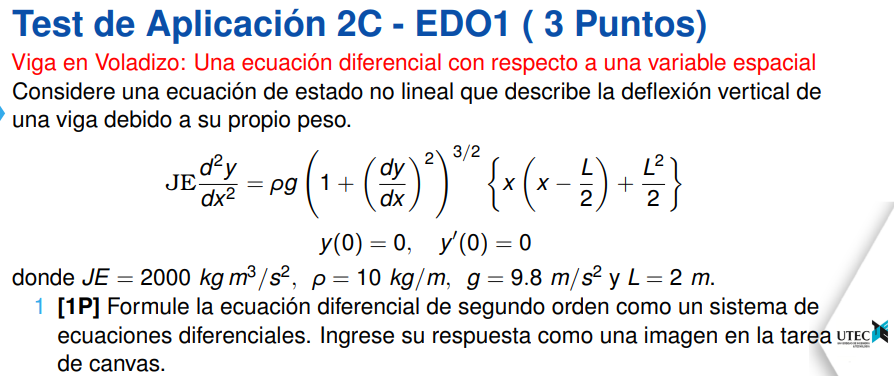

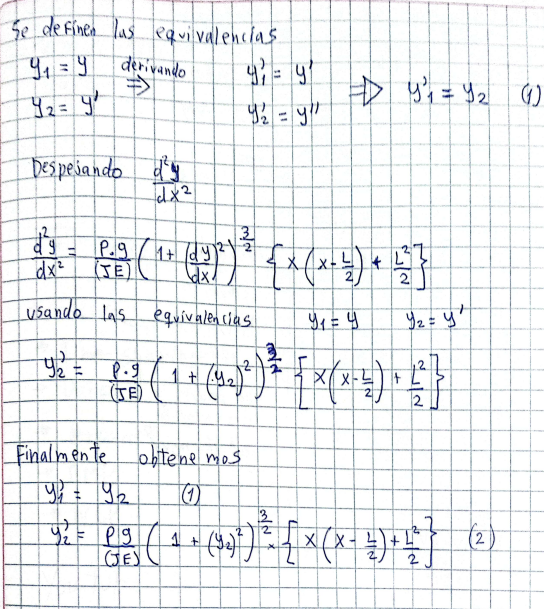

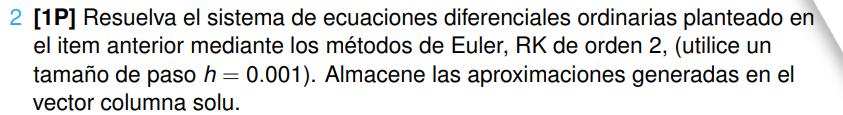

syms y1(x) y2(x)
format long
%se usara una funcion vectorizada que contenga al sistema de ecuaciones
p=10;
g=9.8;
JE=2000;
L=2;

f = @(x, y) [y(2); ( p*g/JE )*( ( 1+(y(2))^2 )^(3/2) )*( x*(x-L/2)+(L^2)/2)]

f = function_handle with value:
    @(x,y)[y(2);(p*g/JE)*((1+(y(2))^2)^(3/2))*(x*(x-L/2)+(L^2)/2)]



y0 = [0;0];
a=0;
b=L;
h=0.001;

res_euler = euler_sistema(f, a, b, y0, h);
res_rk2 = rk2_sistema(f, a, b, y0, h);
solu=zeros(2,1);
solu(1)=res_euler(end,2);
solu(2)=res_rk2(end,2);
solu

solu =    0.198097199742234
   0.198234452725238


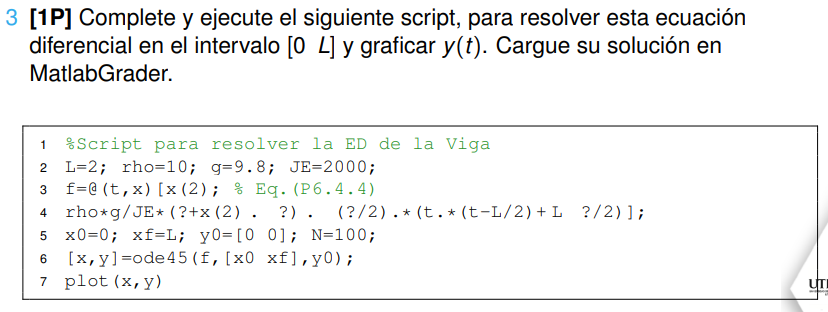

L=2; rho=10; g=9.8; JE=2000;
f=@(t,x) [x(2); (rho*g/JE)*( (1 + x(2).^2 ).^(3/2)).*( t.*(t-L/2) + L^2/2 )]

f = function_handle with value:
    @(t,x)[x(2);(rho*g/JE)*((1+x(2).^2).^(3/2)).*(t.*(t-L/2)+L^2/2)]


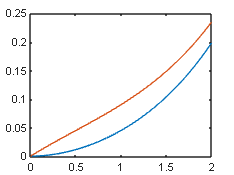

x0=0; xf=L; y0=[0 0]; N=100;
[x,y]=ode45(f,[x0 xf], y0);
plot(x,y)

function z = euler_sistema(f, a, b, y0, h)
t = [a:h:b];
z = [t(1) y0'];
    for k = 1:length(t)-1
        k1 = h*f(t(k), y0);
        y1 = y0+k1;
        z = [z; t(k+1) y1'];
        y0 = y1;
    end
end


function z = rk2_sistema(f, a, b, y0, h)
    t = [a:h:b];
    z = [t(1) y0'];
    for k = 1:length(t)-1
        k1 = h*f(t(k), y0);
        k2 = h*f(t(k+1), y0+k1);
        y1 = y0+1/2*(k1+k2);
        z = [z; t(k+1) y1'];
        y0 = y1;
    end
end
